# EE 146: Computer Vision

# Buddy Ugwumba SID: 862063029

# Lab 1: Matlab Inage Processing Toolbox, Histogram Analysis   

# Date: 01/05/2022

Problem 1: Become familar with image display related functions in matlab

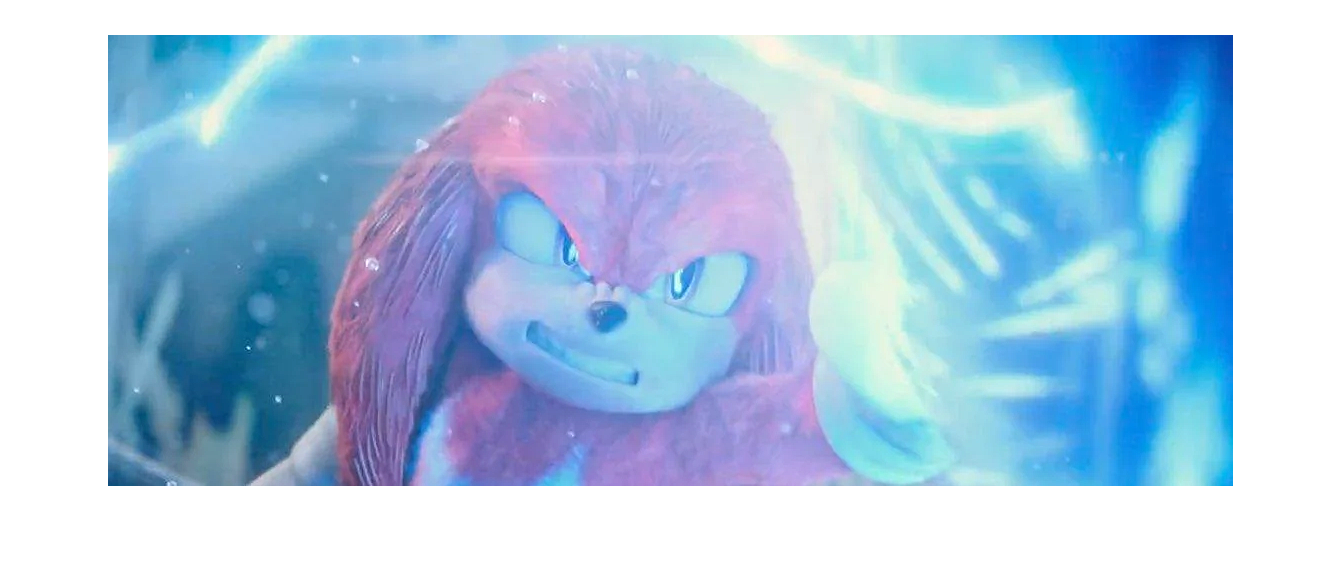

    % Step 1: Basic Image Import, Processing, and Export
    % Use the 'imread' command to read an image into the workspace
        % The image must have that true format, otherwise an error will occur
knuckles = imread('sonic-2-knuckles-1.png');
    % To display the image use the 'imshow' command
% Display color image
imshow(knuckles)

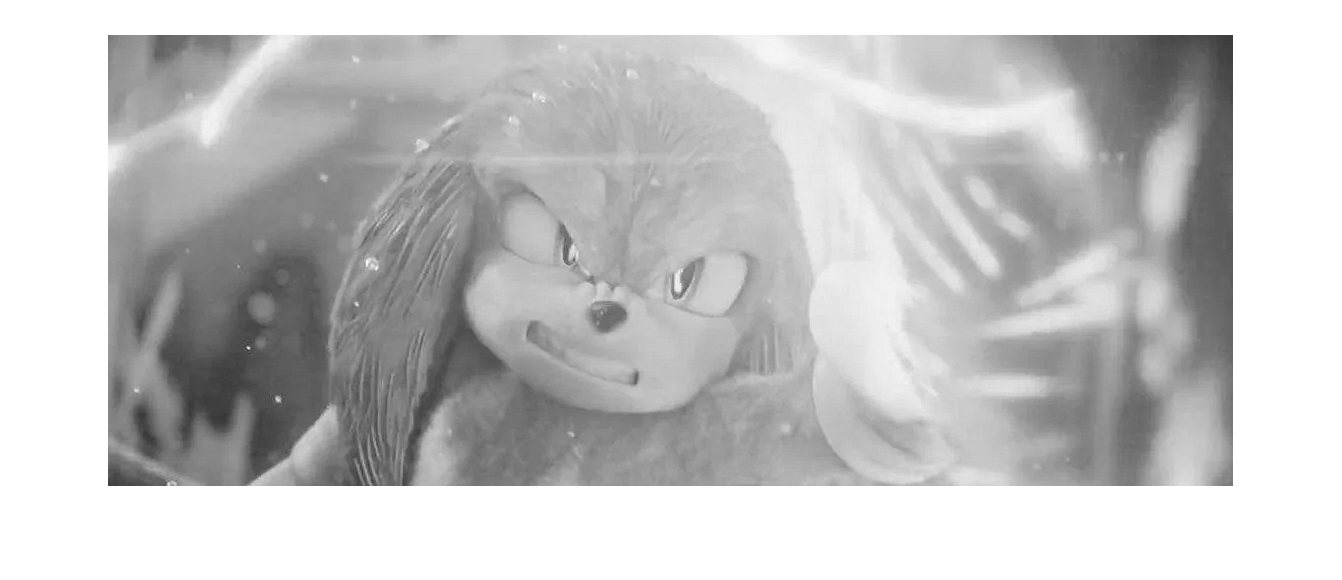

% Display grayscale image using the 'rgb2gray' command
knuckles_grayscale = rgb2gray(knuckles);
imshow(knuckles_grayscale)

The transformation responsible for turning a regular image into a grayscale image is as follows. The function 'rgb2gray' is used with the argument begin the variable holding the image. With this function, the hue and saturation information is removed while the luminance remains.

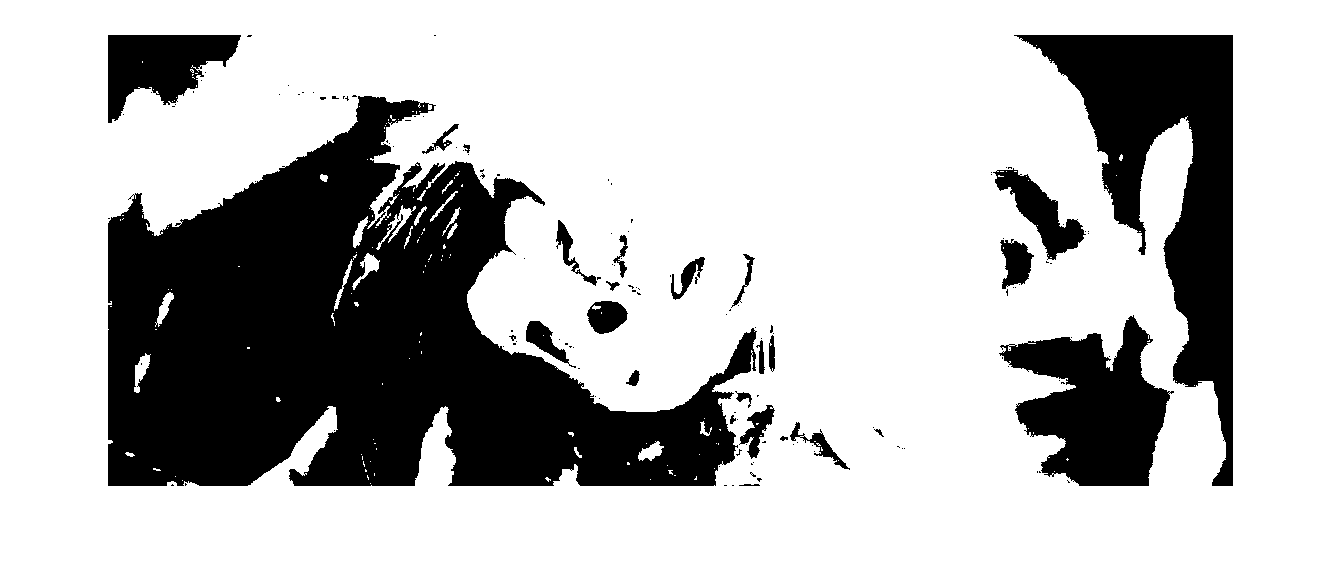

% Display binary image
knuckles_binary = imbinarize(knuckles_grayscale);
imshow(knuckles_binary)

% Determine the number of rows, columns bytes/pixel
whos knuckles

  Name            Size                  Bytes  Class    Attributes

  knuckles      451x1125x3            1522125  uint8              



rows = 451

columns = 1125

bytes = 1522125

Problem 2

(a) Compute and display histograms of a high contrast gray scale image and a low contrast gray scale image

% To compute a histogram of the image use the 'imhist' command

- High contrast gray scale image

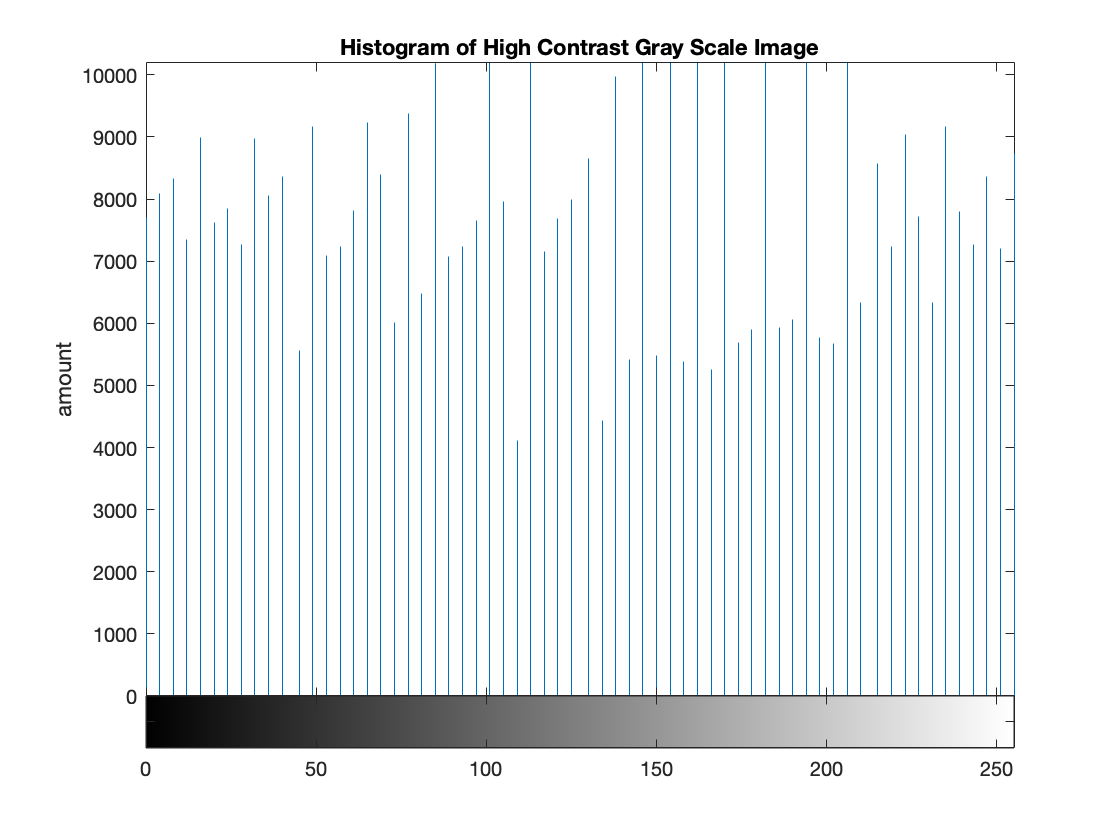

% use the 'histeq' to create a high contrast image of
knuckles_grayscale_high_contrast = histeq(knuckles_grayscale);
figure 
imhist(knuckles_grayscale_high_contrast)
title('Histogram of High Contrast Gray Scale Image')
xlabel("Intensity)")
ylabel("amount")

- Low contrast gray scale image

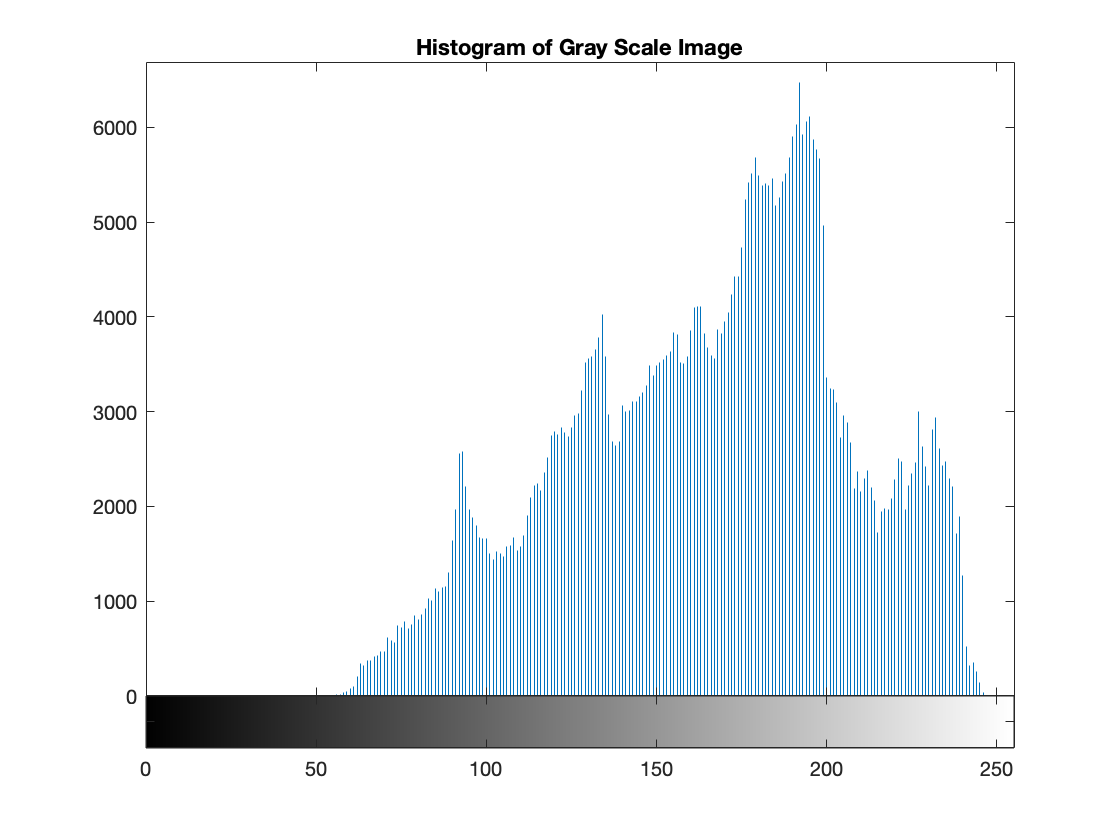

figure 
imhist(knuckles_grayscale)
title('Histogram of Gray Scale Image')

I observe that the intensities of the luminace in the high contrast grayscale's histogram are uniformly distributed over the pixel range. A histogram that is uniformily distributed tells us that the data is vey consistent. Specific to the frequency, each class is very similar to the others. Thus, to increase contrast, we must evenly distribute the luminace across the bit range. The high contrast histogram differs from the low contrast in that the histogram is left skewed . A histogram that is left skewed tells us that the mean is less than the median. There are a few small values that drive the mean downward but do not affect where the exact middle of th data is.

(b) Compute and display histograms of a binary image

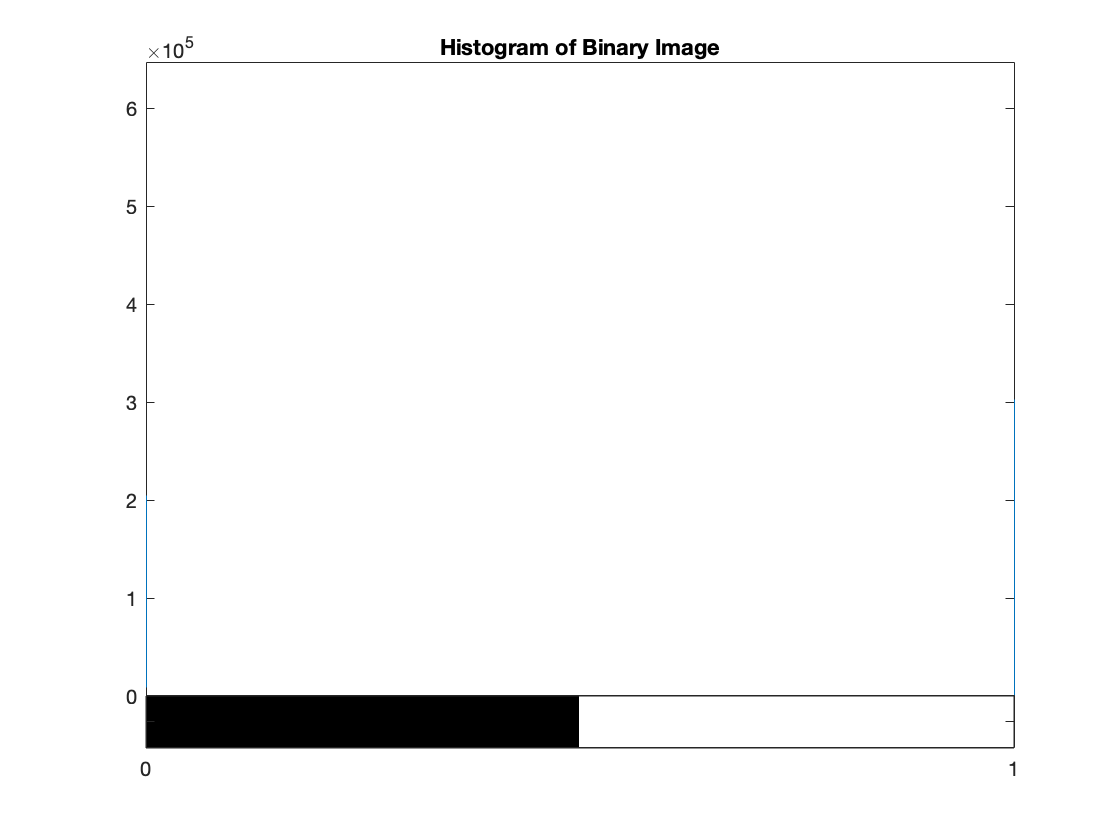

figure 
imhist(knuckles_binary)
title('Histogram of Binary Image')

What I notice about the histogram is that the intensity is half and half with. There are only two bytes available on the x axis which is 0 and 1. Also there are two spikes in the 0 marker and the 255 marker. These two spikes represent the on and off portion of the image (light or dark).

(c) (i) Compute and display the histogram of a color inage by its individual color channels

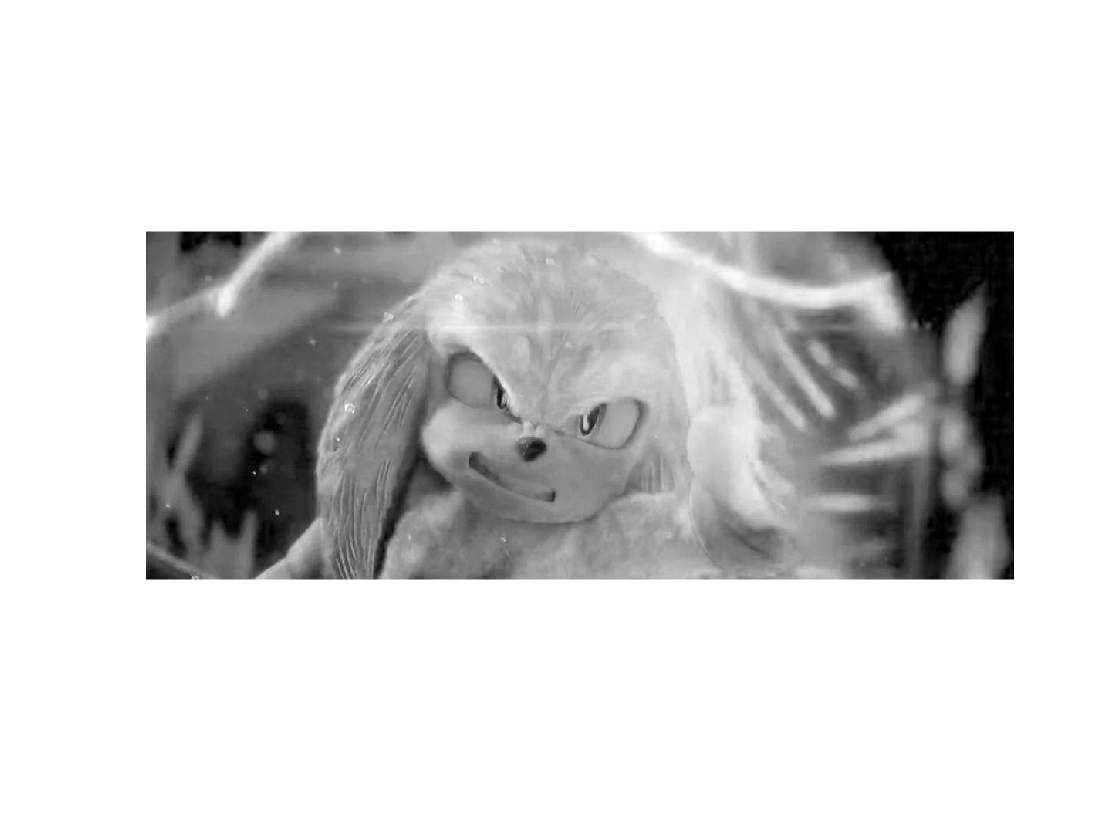

% Extract color channels.
% Image(height, width, channel)
redKnuckles = knuckles(:,:,1); % Red channel
greenKnuckles = knuckles(:,:,2); % Green channel
blueKnuckles = knuckles(:,:,3); % Blue channel
% Create an all black channel.
% 'uint8' stands for unsigned 8 bit integer 2^8 (0 - 255)
% because 'unit8' is unsigned, its MSB is not reserved for signing
allBlack = zeros(size(knuckles, 1), size(knuckles, 2), 'uint8');

imshow(redKnuckles)

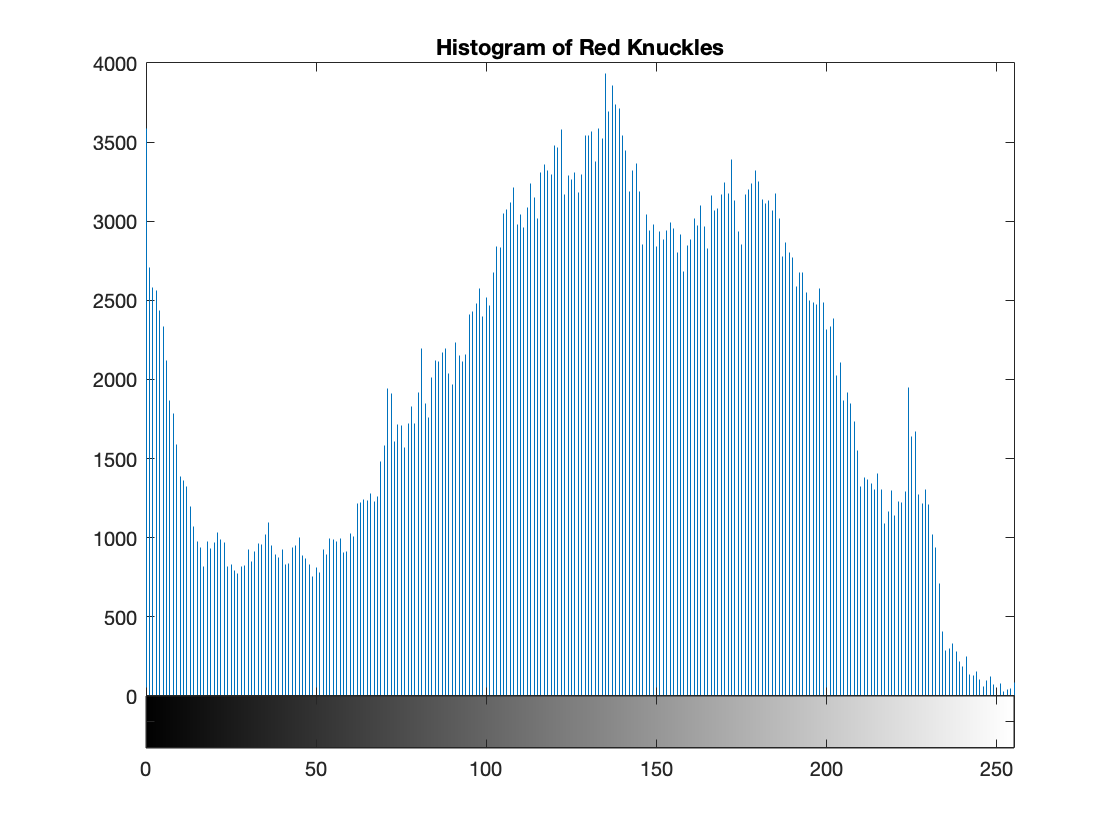

imhist(redKnuckles)
title('Histogram of Red Knuckles')
ylim([0,4000])

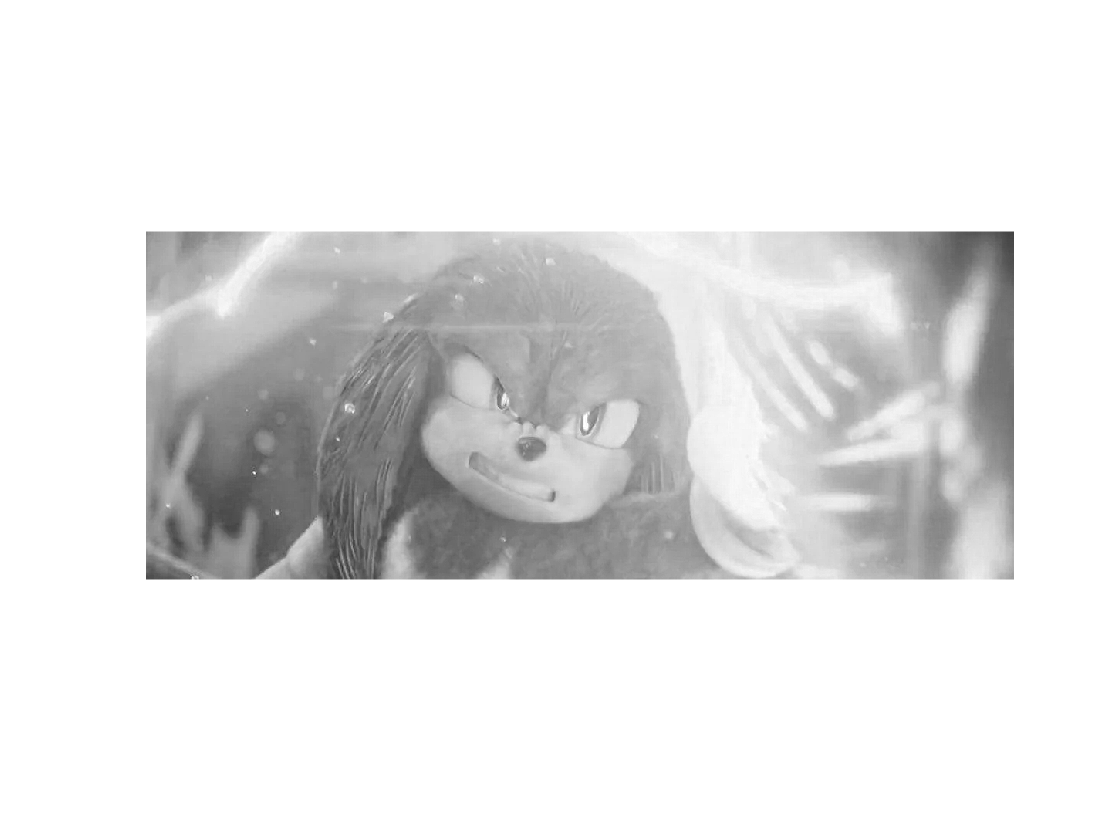

imshow(greenKnuckles)

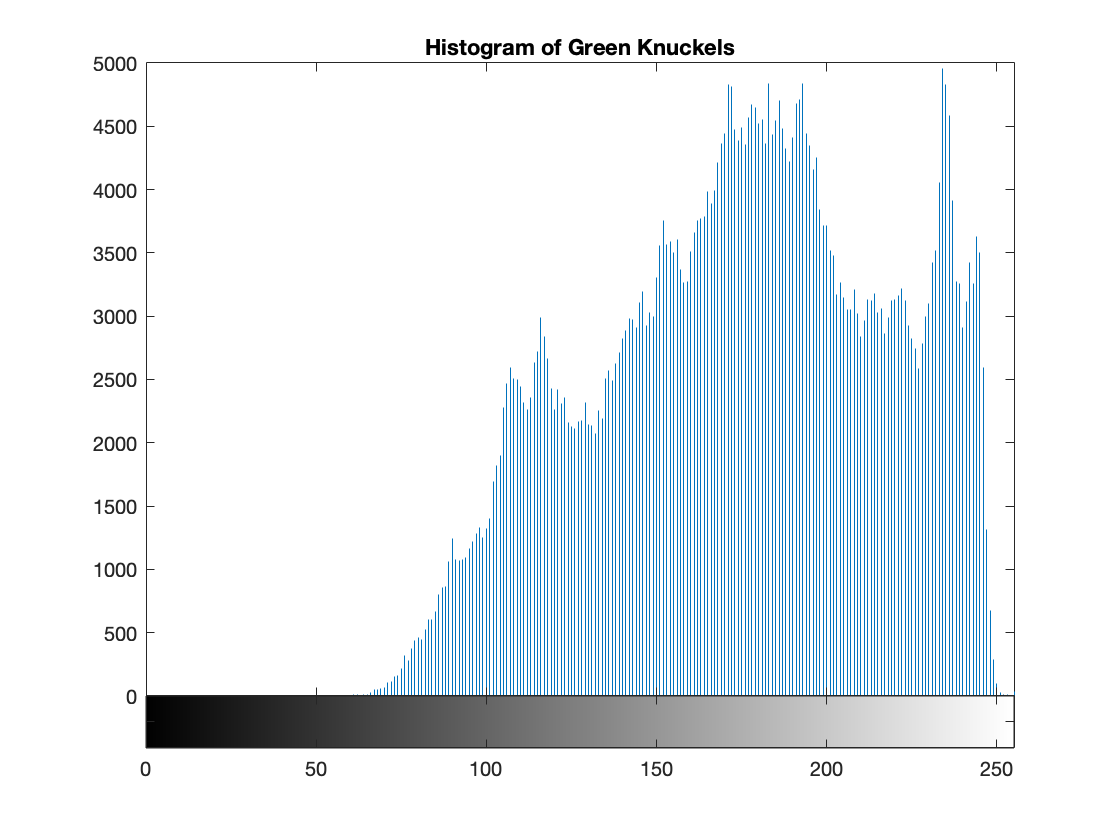

figure
imhist(greenKnuckles)
title('Histogram of Green Knuckels')
ylim([0,5000])

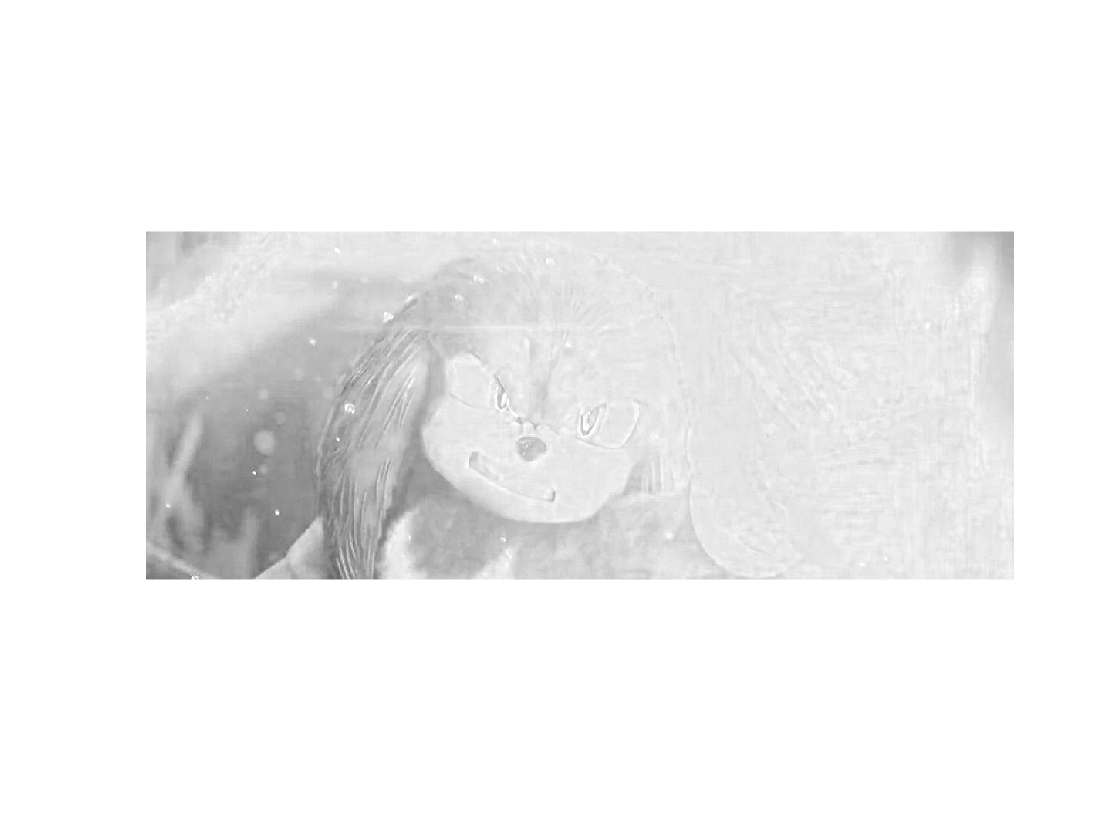

imshow(blueKnuckles)

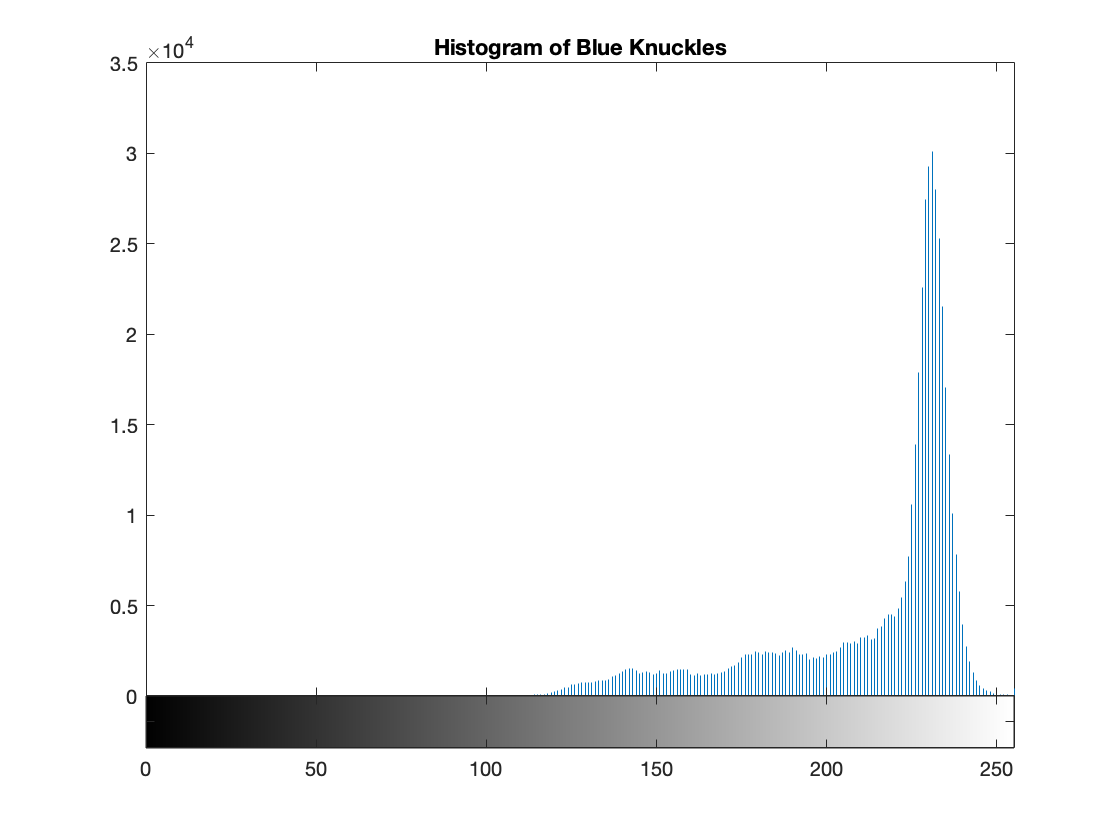

figure
imhist(blueKnuckles)
title('Histogram of Blue Knuckles')
ylim([0,35000])

(ii) Display the combined histogram of a 24 bit color image by concatenating the values of R, G, B channels/images in a single histogram vector of length 256x3 rather than having three vectors, each of length 256

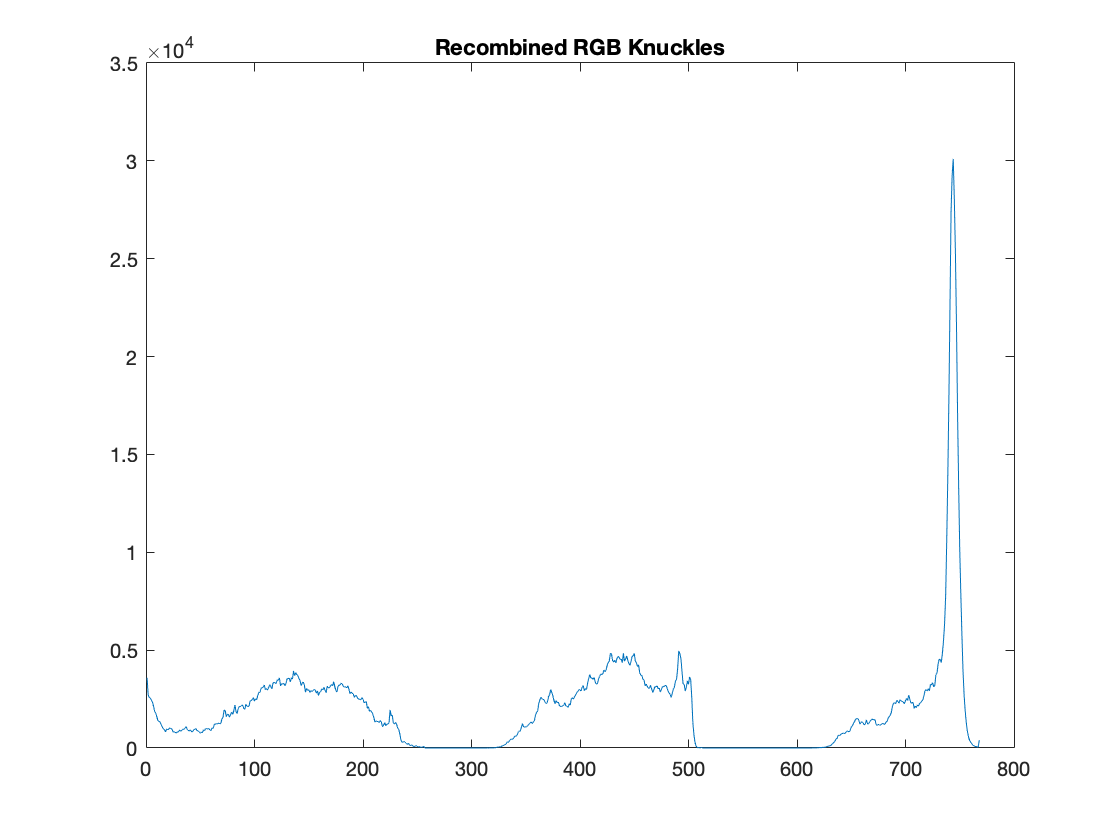

% Recombine the individual color channels to create the original RGB image again.
% The first argument is the dimension that you want to concatenate
recombinedKnuckles = cat(1, imhist(redKnuckles), imhist(greenKnuckles), imhist(blueKnuckles));
figure
plot(recombinedKnuckles)
title('Recombined RGB Knuckles')

This image represents the concatenation of the three individual histograms from the channels. 

(iii) Obtain the 8 bit histogram of a color image

% Obtain the 3 MSB from each indexed value the red and green channel
% and the 2 MSB from the blue channel
% Make that a single value
eight_bit = zeros(size(redKnuckles));
for i = 1:size(redKnuckles,1)
    for j = 1:size(redKnuckles,2)
        entry = dec2bin(redKnuckles(i,j), 8);
        entry = entry(1:3);
        entry1 = dec2bin(greenKnuckles(i,j), 8);
        entry1= entry1(1:3);
        entry2 = dec2bin(blueKnuckles(i,j), 8);
        entry2 = entry2(1:2);
        eight_bit_knuckles = cat(2, entry, entry1, entry2);
        eight_bit_knuckles = bin2dec(eight_bit_knuckles);
        eight_bit(i,j) = eight_bit_knuckles;    
    end
end


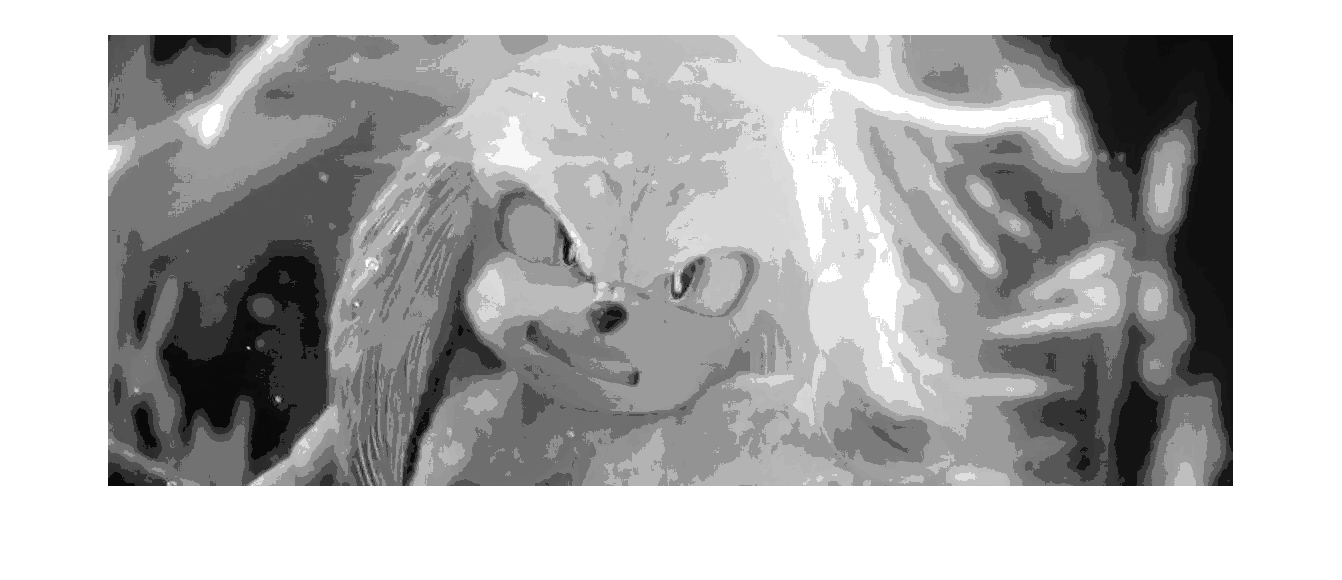

% Display the image
% Convert indexed values into unsigned int
eight_bit = uint8(eight_bit);
imshow(eight_bit)

(d) Compute and display cumulative histogram of an image

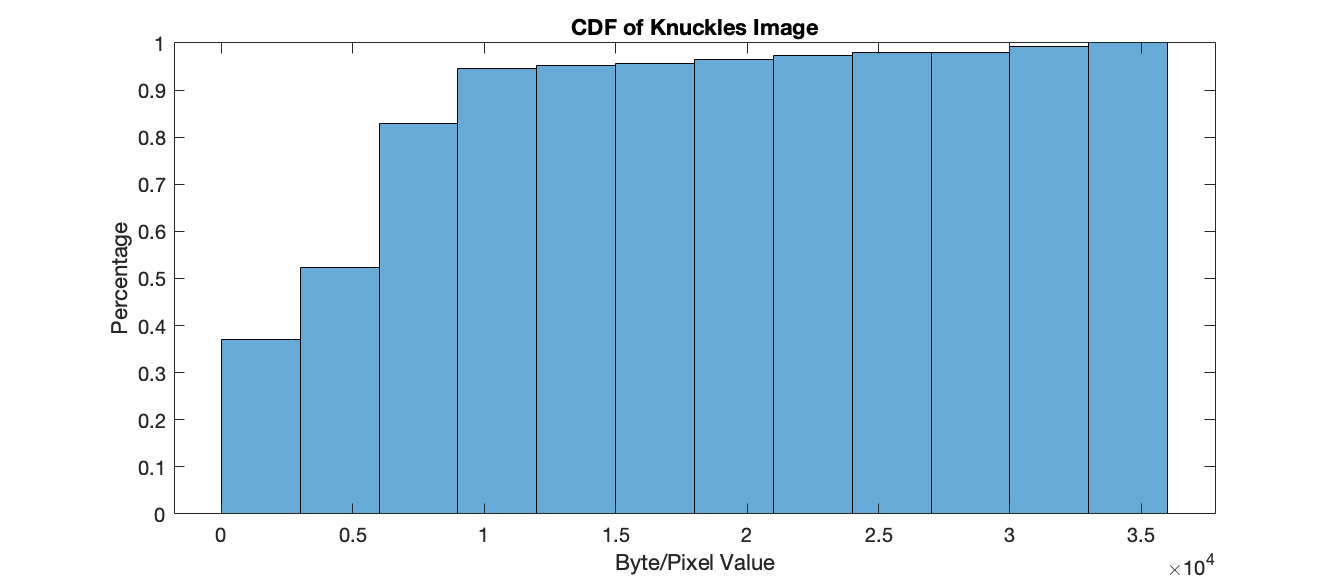

% Use normalized histogram to obtain cumulative histogram
normal_knuckles = imhist(knuckles);
histogram(normal_knuckles,'Normalization','cdf');
title('CDF of Knuckles Image')
xlabel('Byte/Pixel Value')
ylabel('Percentage')

The CDF of an image tells us what percentage of the bytes/pixel make up the image.

(e) Compute statistical properties of an image

- Mean

% The mean of the knuckles color image without respect to color channel is:
mean = mean2(knuckles)

mean = 172.3607

The mean tell us the typical or central point value of the bytes/pixel

- Variance

% The variance of the knuckles color image without respect to color channel
var_knuckles = double(imread('sonic-2-knuckles-1.png'));
variance = var(var_knuckles(:))

variance = 3.2313e+03

The variance tells us the degree of spread in data set. The data is very spread because the variance is much larger than the mean

- Median

% The median of the knuckles color image without respect to color channel
median = median(knuckles(:))

median = uint8
182

The median tells us the middle value of the byte/pixel in the data set